Teste do Live Editor

Fonte: https://www.mathworks.com/help/control/ug/kalman-filtering.html

A = [1.1269   -0.4940    0.1129;
     1.0000         0         0;
          0    1.0000         0]

A =     1.1269   -0.4940    0.1129
    1.0000         0         0
         0    1.0000         0



B = [-0.3832;
      0.5919;
      0.5191]

B =    -0.3832
    0.5919
    0.5191



C = [1 0 0]

C =      1     0     0


Plant = ss(A,[B B],C,0,-1,'inputname',{'u' 'w'},'outputname','y');
Q = 1;
R = 1;
[kalmf,L,P,M] = kalman(Plant,Q,R);
M

M =     0.3798
    0.0817
   -0.2570


kalmf = kalmf(1,:);

a = A;
b = [B B 0*B];
c = [C;C];
d = [0 0 0;0 0 1];
P = ss(a,b,c,d,-1,'inputname',{'u' 'w' 'v'},'outputname',{'y' 'yv'});

sys = parallel(P,kalmf,1,1,[],[]);

SimModel = feedback(sys,1,4,2,1);   % Close loop around input #4 and output #2
SimModel = SimModel([1 3],[1 2 3]); % Delete yv from I/O list
SimModel.InputName

ans =     'w'
    'v'
    'u'


SimModel.OutputName

ans =     'y'
    'y_e'


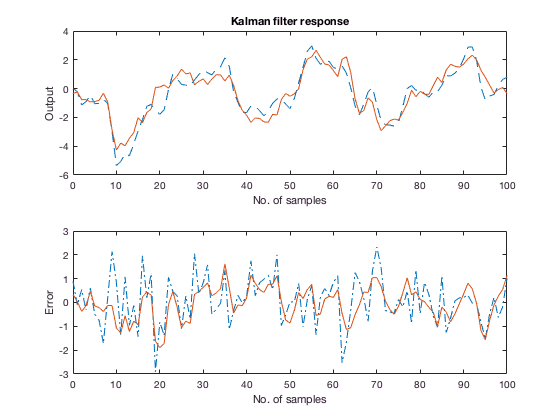

t = [0:100]';
u = sin(t/5);

n = length(t);
rng default
w = sqrt(Q)*randn(n,1);
v = sqrt(R)*randn(n,1);

[out,x] = lsim(SimModel,[w,v,u]);

y = out(:,1);   % true response
ye = out(:,2);  % filtered response
yv = y + v;     % measured response

subplot(211), plot(t,y,'--',t,ye,'-'),
xlabel('No. of samples'), ylabel('Output')
title('Kalman filter response')
subplot(212), plot(t,y-yv,'-.',t,y-ye,'-'),
xlabel('No. of samples'), ylabel('Error')

MeasErr = y-yv;
MeasErrCov = sum(MeasErr.*MeasErr)/length(MeasErr)

MeasErrCov = 0.9992

EstErr = y-ye;
EstErrCov = sum(EstErr.*EstErr)/length(EstErr)

EstErrCov = 0.4944